# Analyse de Donées - TD3

A firt look on Support Vector Machine

28_11_22

clc; clear all; close all;

X = [randn(100,2) + 1.5*ones(100,2); ... 
     randn(100,2) - 1.5*ones(100,2)]

X =     0.5531    1.6109
    0.6531    1.1893
    1.7923    0.9219
   -0.6843    1.9755
    0.3256    2.2214
   -0.0658    0.1299
    1.1721    2.6101
    1.9852    1.6488
    3.8648    1.2640
    1.4959   -0.0885


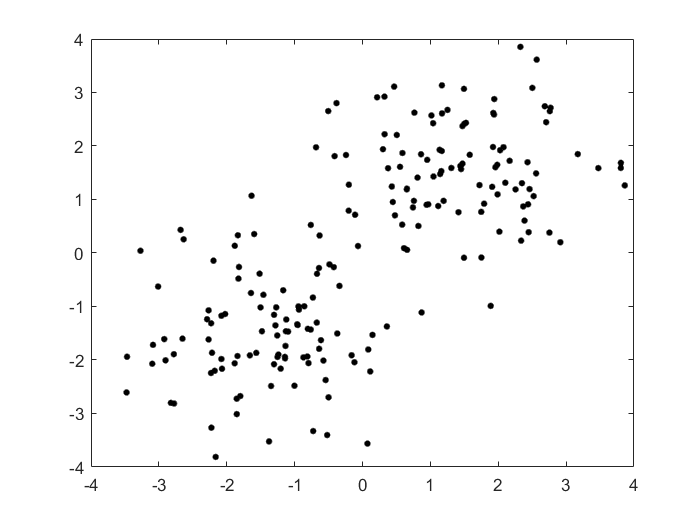

figure(1)
plot( X(:,1), X(:,2), 'k.', 'MarkerSize', 12)

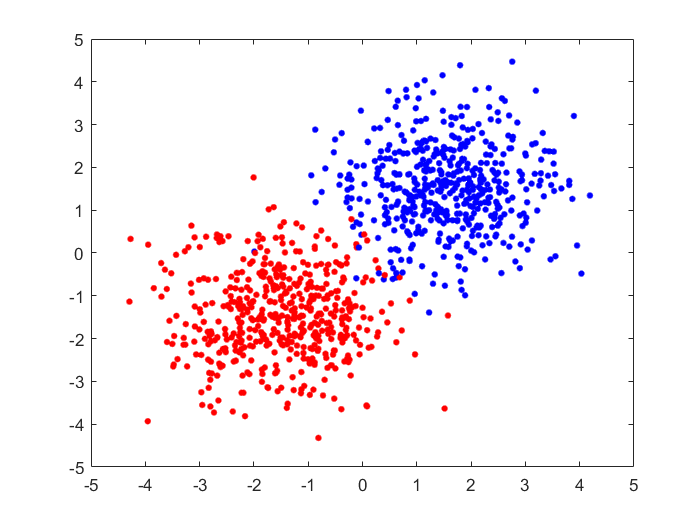

figure(2)
plot( X(1:100, 1), X(1:100, 2), 'b.', 'MarkerSize', 12 )
hold on
plot( X(101:200, 1), X(101:200, 2), 'r.', 'MarkerSize', 12)

opts = statset('Display', 'final');
% identify k number of clusters. In this example below k = 2 and te dataset
% is X.
[idx, ctrs] = kmeans( X, 2, 'Distance', 'sqeuclidean', ...
                      'Replicates', 5, 'Options', opts)             

Replicate 1, 3 iterations, total sum of distances = 360.925.
Replicate 2, 2 iterations, total sum of distances = 360.879.
Replicate 3, 3 iterations, total sum of distances = 360.879.
Replicate 4, 3 iterations, total sum of distances = 360.925.
Replicate 5, 4 iterations, total sum of distances = 360.925.
Best total sum of distances = 360.879


idx =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


ctrs =    -1.4311   -1.5109
    1.4488    1.5880


https://www.youtube.com/watch?v=4b5d3muPQmA

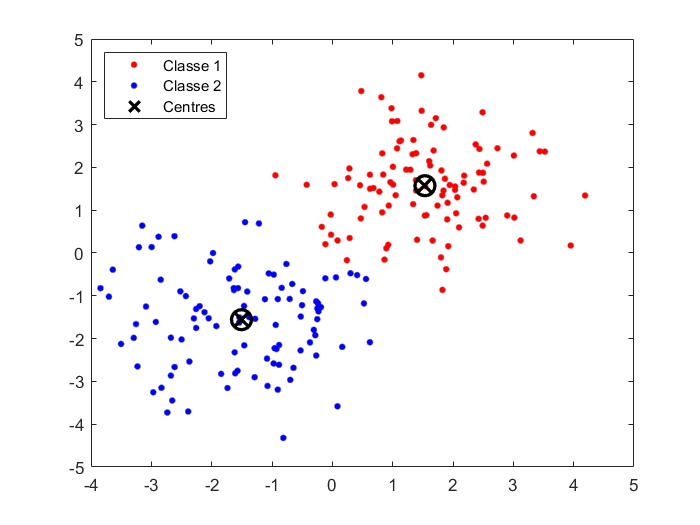

figure(3)       
plot( X(idx == 1, 1), X(idx == 1, 2), 'r.', 'MarkerSize', 12)
hold on
plot(X(idx == 2, 1), X(idx == 2, 2), 'b.', 'MarkerSize', 12)
plot(ctrs(:, 1), ctrs(:, 2), 'kx', 'MarkerSize', 12, 'LineWidth', 2)
plot(ctrs(: ,1), ctrs(:, 2), 'ko', 'MarkerSize', 12, 'LineWidth', 2)
legend('Classe 1', 'Classe 2', 'Centres', 'Location', 'NW')